## Step 0 选择文件

% wavFileName = "./records/mono/static_20cm_silent_1.wav";
% wavFileName = "./records/mono/static_40cm_silent_1.wav";
% wavFileName = "./records/mono/static_40cm_silent_2.wav";
% wavFileName = "./records/mono/dynamic_20to40cm_noisy_1.wav";
% wavFileName = "./records/mono/dynamic_20to40cm_noisy_2.wav"; % 这个实验数据好像不太对
% wavFileName = "./records/mono/dynamic_20to40cm_noisy_3.wav";
% wavFileName = "./records/mono/dynamic_10to40cm_silent_1.wav";
% wavFileName = "./records/mono/dynamic_10to20cm_silent_1.wav";
% wavFileName = "./records/mono/dynamic_fast10to20cm&slow20to30_silent_1.wav";
% wavFileName = "./records/mono/dynamic_10to20&20to40&40to25_silent.wav";
% wavFileName = "./records/mono/dynamic_10to20&20to30_silent.wav";
% wavFileName = "./records/mono/dynamic/30d_10to20&20to30&30to20_silent.wav";
% wavFileName = "./records/mono/dynamic/10to20&20to40&40to20_silent.wav";
% wavFileName = "./records/mono/dynamic/v_10to30_silent.wav";

% 报告用
% wavFileName = "./records/report/rubbish/5m.wav";
% wavFileName = "./records/mono/report/1m_2.wav";


% wavFileName = "./records/report/distance/80cm_1.wav";   % good!
% wavFileName = "./records/report/distance/80cm_2.wav";

% wavFileName = "./records/report/distance/70cm_1.wav";
% wavFileName = "./records/report/distance/70cm_2.wav";     % good

% wavFileName = "./records/report/distance/60cm_1.wav";       % good
% wavFileName = "./records/report/distance/60cm_2.wav";       % good

% wavFileName = "./records/report/distance/50cm_1.wav";       % good
% wavFileName = "./records/report/distance/50cm_2.wav";       % good
% wavFileName = "./records/report/distance/50cm_3.wav";       % good

% wavFileName = "./records/report/distance/40cm_1.wav";       % good
% wavFileName = "./records/report/distance/40cm_2.wav";       % very bad   
% wavFileName = "./records/report/distance/40cm_3.wav";       % very good


% wavFileName = "./records/report/speed/20_30_10_20_v1_2.wav";
% wavFileName = "./records/report/speed/20_30_10_20_v2.wav";
% wavFileName = "./records/report/speed/20_30_10_20_v2_2.wav";  
% wavFileName = "./records/report/speed/20_30_10_20_v3.wav";  

% wavFileName = "./records/report/speed/40_50_40_30_v2.wav";  
% wavFileName = "./records/report/speed/40_50_40_30_v3.wav"; 

% 角度
% wavFileName = "./records/report/angle/20_1.wav"; 
% wavFileName = "./records/report/angle/20_2.wav"; 


% wavFileName = "./records/report/angle/20_2.wav"; 
% 
% wavFileName = "./records/report/angle/20_2.wav";  % good
% wavFileName = "./records/report/angle/30_4.wav";  % good
% wavFileName = "./records/report/angle/40_4.wav";    % goSod
% wavFileName = "./records/report/angle/50_2.wav";    % good

% wavFileName = "./records/report/angle2/40_2.wav";    % good

% wavFileName = "./records/report/angle3/20_1.wav";    % good
% wavFileName = "./records/report/angle3/30_1.wav";    % good
% wavFileName = "./records/report/angle3/40_2.wav";    % good
% wavFileName = "./records/report/angle3/50_2.wav";    % good

% wavFileName = "./records/report/noise/quiet.wav";    % good
% wavFileName = "./records/report/noise/soft_2.wav";    % good
% wavFileName = "./records/report/noise/pop_1.wav";    % good
% wavFileName = "./records/report/noise/white_noise_1.wav";    % good

wavFileName = "./records/report/noise2/4_5.wav";    % good

## Step 1 展示原始信号

frequencyOfSample = 44100;
[recordY, recordFs] = audioread(wavFileName);
recordY = recordY(44101:length(recordY)) % 去除第一秒的数据

recordY =    -0.0794
    0.0381
   -0.0816
    0.0082
   -0.0459
   -0.0052
    0.0159
   -0.0215
    0.0564
   -0.0486


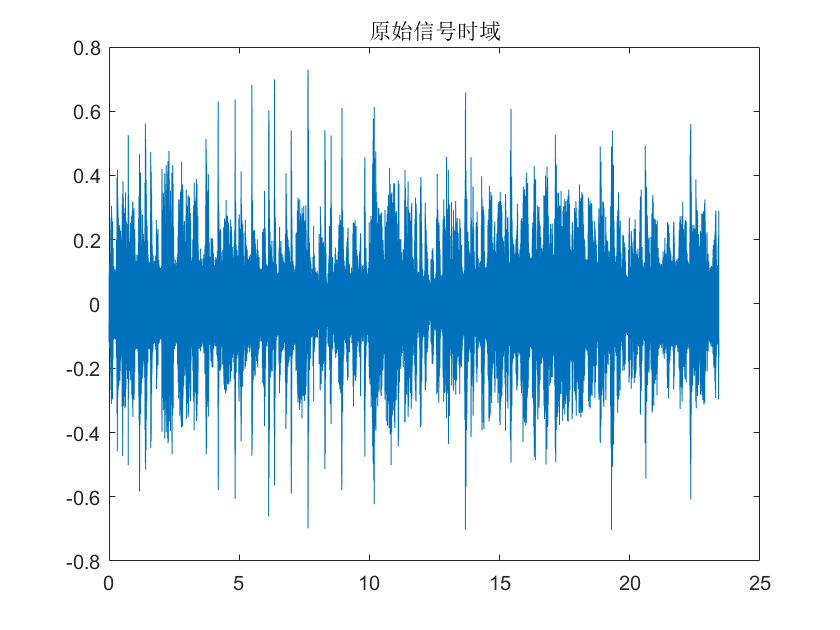

% 展示原始数据
len = length(recordY);
%% 时域处理
t = (0:len-1)/recordFs;
plot(t, recordY);
title("原始信号时域")

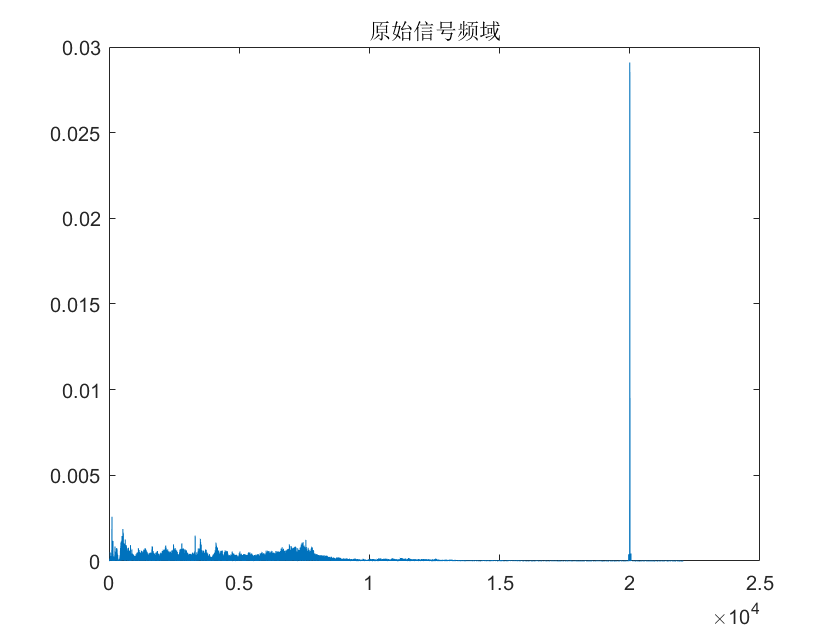

%% 频域处理
fftY = abs(fft(recordY)) / (len / 2);
fftY(1) = fftY(1) / 2;
f = recordFs * (0:len - 1) / len;
% 整体图
plot(f(1:ceil(len/2)), fftY(1:ceil(len/2)));
title("原始信号频域")

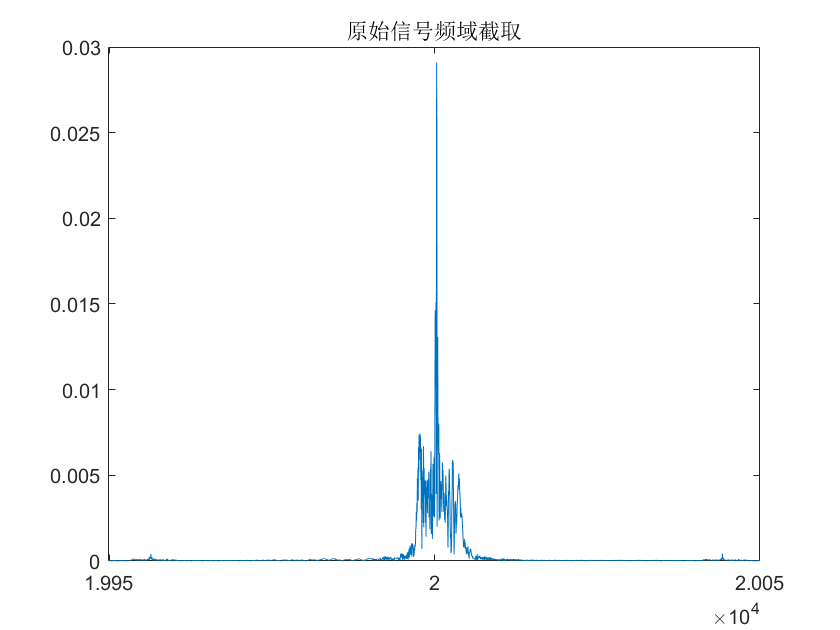

% 部分图
plotBandWidth = 50;
beginFrequncy = 20000 - plotBandWidth;
endFrequncy = 20000 + plotBandWidth;
beginIndex = floor(beginFrequncy / recordFs * len);
endIndex = ceil(endFrequncy / recordFs * len);
plot(f(beginIndex:endIndex), fftY(beginIndex:endIndex));
title("原始信号频域截取")

## Step 2 滤波后展示信号

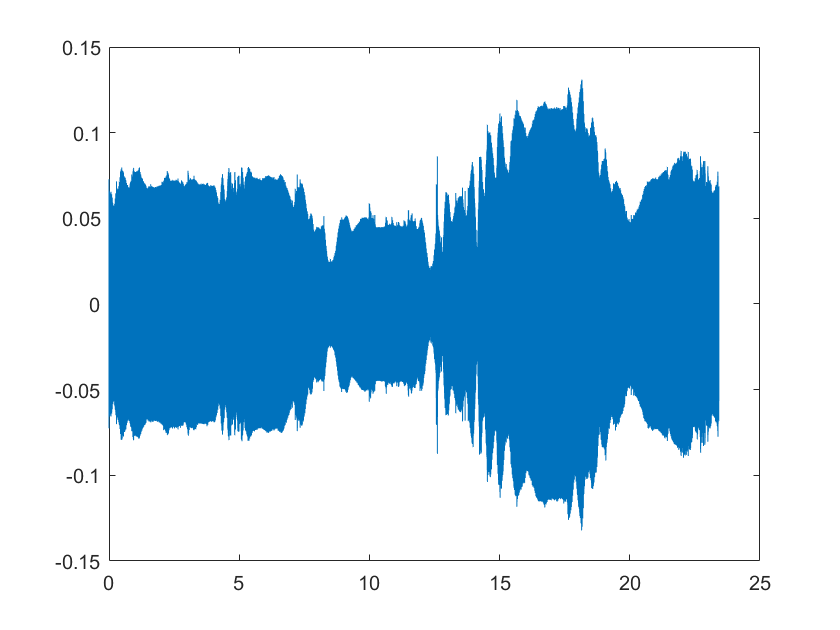

% step2 进行一次带通滤波
filteredY = filter(myFilter, recordY);
% 展示原始数据
len = length(filteredY);
%% 时域处理
t = (0:len-1)/recordFs;
plot(t, filteredY);

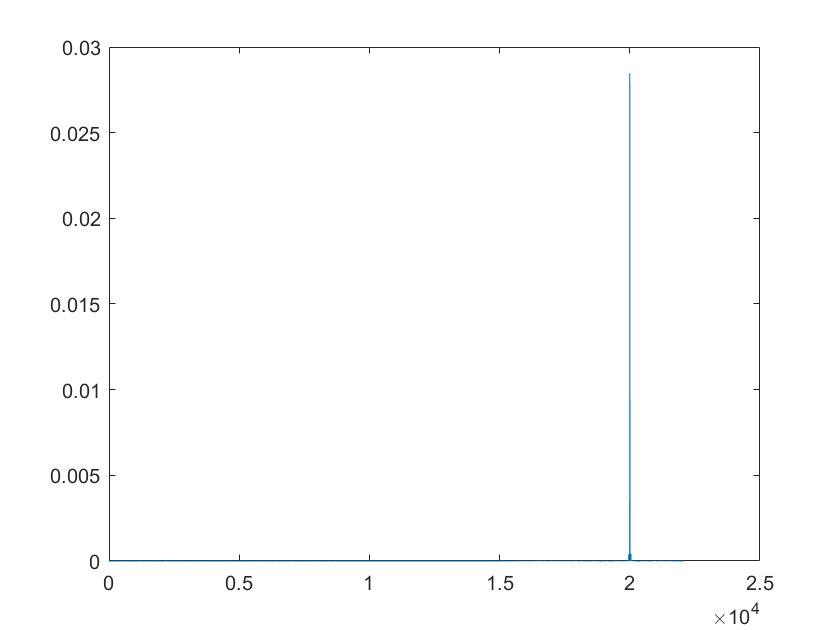

%% 频域处理
fftY = abs(fft(filteredY)) / (len / 2);
fftY(1) = fftY(1) / 2;
f = recordFs * (0:len - 1) / len;
% 整体图
plot(f(1:ceil(len/2)), fftY(1:ceil(len/2)));

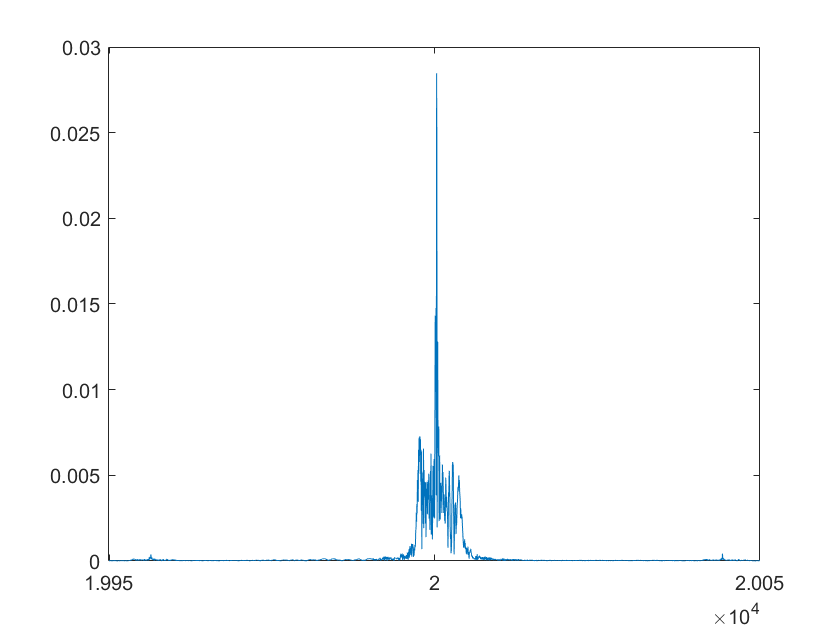

% 部分图
plotBandWidth = 50;
beginFrequncy = 20000 - plotBandWidth;
endFrequncy = 20000 + plotBandWidth;
beginIndex = floor(beginFrequncy / recordFs * len);
endIndex = ceil(endFrequncy / recordFs * len);
plot(f(beginIndex:endIndex), fftY(beginIndex:endIndex));

## Step 3 展示局部最大值

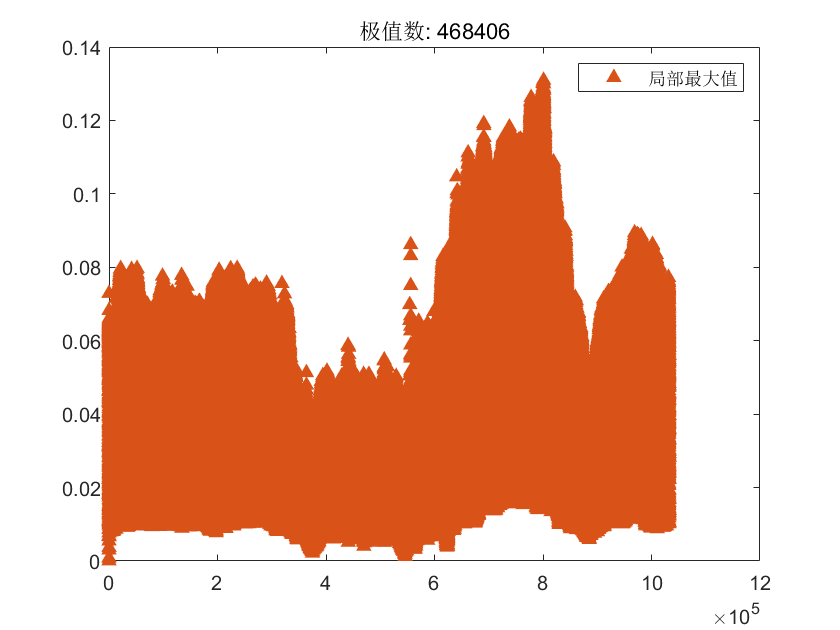

% 查找局部最大值
maxIndices = islocalmax(filteredY);

% 显示结果
clf

% 绘制局部最大值
plot(find(maxIndices),filteredY(maxIndices),'^','Color',[217 83 25]/255,...
    'MarkerFaceColor',[217 83 25]/255,'DisplayName','局部最大值')
title(['极值数: ' num2str(nnz(maxIndices))])
legend

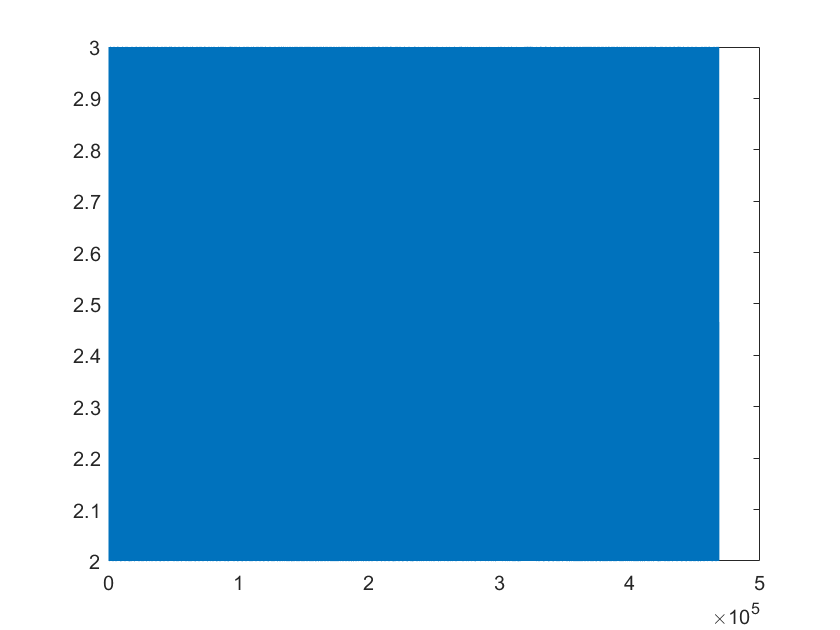

localMaxmiumIndexes = find(maxIndices);
numberOfLocalMaxmium = length(localMaxmiumIndexes);
intervalOfLocalMaxmium = localMaxmiumIndexes(2:numberOfLocalMaxmium) - localMaxmiumIndexes(1:numberOfLocalMaxmium - 1);
plot((1:numberOfLocalMaxmium - 1), intervalOfLocalMaxmium(1:numberOfLocalMaxmium - 1));


fprintf("Number of local maximum: %d", numberOfLocalMaxmium);

Number of local maximum: 468406

fprintf("Expected number of local maximum for origin signal: %d", len / recordFs * 20000)

Expected number of local maximum for origin signal: 4.684000e+05

## Step 4 计算LMP

LMP = zeros(len, 1);
LMP(1) = double(maxIndices(1));
for i = 2:len
    LMP(i) = LMP(i - 1) + double(maxIndices(i));
end

## Step5 计算lmps的差

% LMPS的窗口大小，单位为样本数
lmpsWindowSize = 500;
% 计算频率，每隔多少个样本计算一次相位差
resultInterval = 100;

### 尝试：以第一个窗口为标准，直接计算总相位差

startSum = sum(LMP(1:lmpsWindowSize));
resultNum = ceil((len - lmpsWindowSize) / resultInterval);
totalLmpChange = zeros(1, resultNum);
for i = 1:(ceil((len - lmpsWindowSize) / resultInterval) - 1)
    tSum = sum(LMP(i * resultInterval:i*resultInterval + lmpsWindowSize));
    totalLmpChange(i + 1) = (tSum - startSum);
end

## Step 6 计算相位差，及位移差

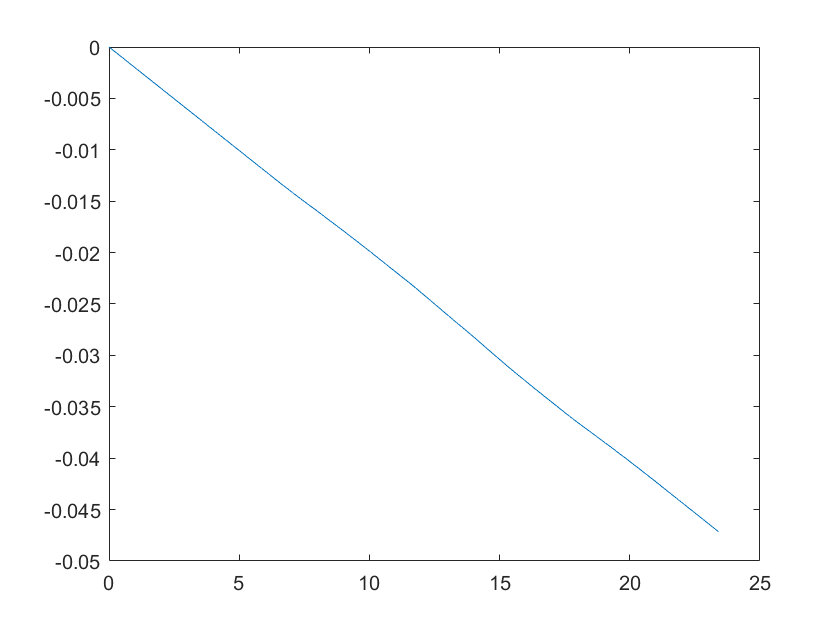

speedOfSound = 34000; % 音速，单位厘米每秒
totalPhaseChange = totalLmpChange * 2 * pi / lmpsWindowSize;
st = (0:resultNum - 1) * resultInterval / recordFs;
% 做一步频率修正（时钟同步）
% 

alphaF = 20000;
tmp = st - (totalPhaseChange / (2 * pi * alphaF));
plot(st, tmp);

% 线性拟合一下这个结果
stasticNum = floor((2 * frequencyOfSample - lmpsWindowSize) / resultInterval)

stasticNum = 877

linearFit = polyfit(st(1:stasticNum), tmp(1:stasticNum), 1)

linearFit =    -0.0020    0.0000


% alphaF = alphaF * (1 - linearFit(1))
alphaF = totalPhaseChange(stasticNum) / (2 * pi * st(stasticNum))

alphaF = 2.0040e+04

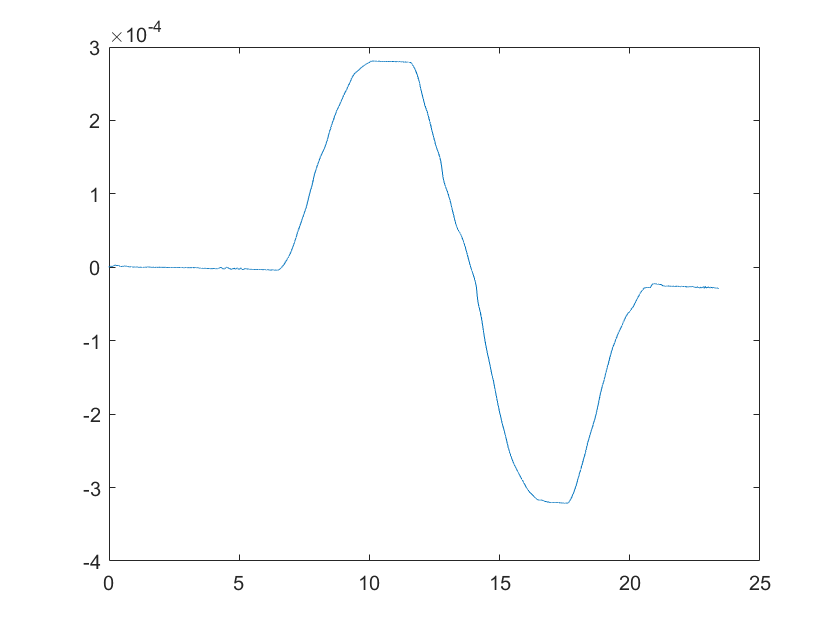

tmp = st - (totalPhaseChange / (2 * pi * alphaF));
plot(st, tmp);

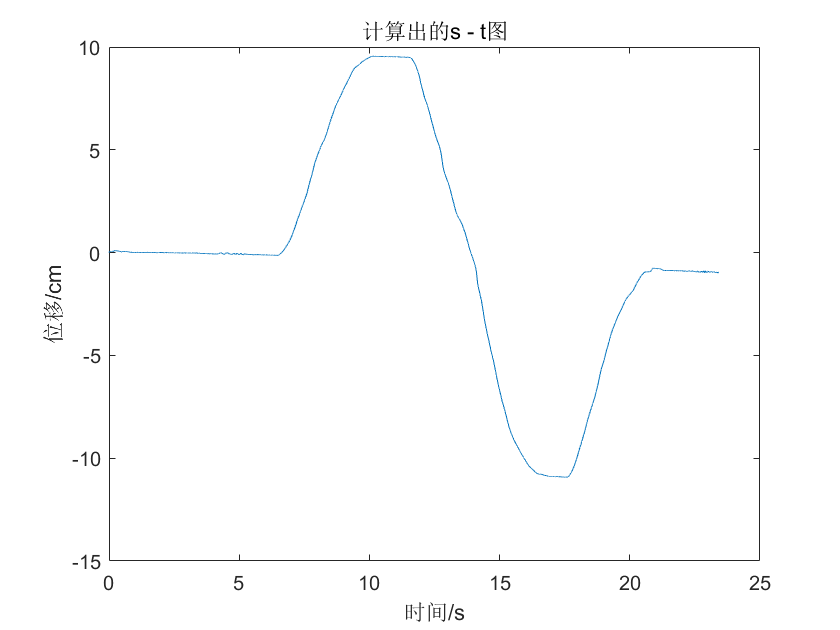

totalDistanceChange = speedOfSound * (st - totalPhaseChange / (2 * pi * alphaF));
plot(st, totalDistanceChange);
xlabel('时间/s')
ylabel('位移/cm')
title("计算出的s - t图")